clear
rng(203829)
addpath('functions') % Make sure your functions F_ct, dF_ct, G_ct are accessible
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
plotPos = [100 100 800, 400];
plotPos2 = [100 100 800, 600];


% System Parameters
kappa = 5*10^-5;
lambda = 3;
Lambda = 5*10^-5;
beta = 0.0065;
H = 0.05;

n_states = 3; % Number of states [x1, x2, x3]
n_inputs = 1; % Number of inputs [u]

% Process Noise Covariance
Rv = diag([1, 1, 10^-8]);

% Measurement Noise Covariance
Re = diag([0.1, 0.1]);
n_outputs = size(Re, 1); % Number of outputs (will be 2)
n_outputs_c = size(1, 1); % Number of outputs (will be 2)

% Output matrix C
C = [1, 0, 0; % Measure x1 (neutron concentration)
     0, 1, 0]; % Measure x2 (delayed neutron precursor concentration)
Co = [1,0,0];


dt = 10^-3;   % Simulation/Euler time step

% Continuous-time system functions
% Function defining the state derivatives dx/dt = F_ct(x) + G_ct(x)u
function dxdt = F_ct(t,x0)
    kappa = 5*10^-5;
    lambda = 3;
    Lambda = 5*10^-5;
    beta = 0.0065;
    H = 0.05;
    dxdt = [
       (x0(3) - beta)/Lambda * x0(1) + lambda * x0(2);
       beta/Lambda * x0(1) - lambda * x0(2);
       -kappa*H*x0(1);
    ];
end

% Jacobian of F_ct w.r.t x (d(F_ct)/dx)
function JF = dF_ct(x0)
    lambda = 3;
    Lambda = 5*10^-5;
    beta = 0.0065;
    kappa = 5*10^-5;
    H = 0.05;
    JF = [
       (x0(3) - beta)/Lambda,  lambda, x0(1)/Lambda;
       beta/Lambda, - lambda, 0;
       -kappa*H, 0, 0;
    ];
end

% Function defining the input mapping G_ct(x)
function B_ct = G_ct(x0)
    Lambda = 5*10^-5;
    B_ct = [
       x0(1)/Lambda;
       0;
       0;
    ];
end

% Jacobian of G_ct w.r.t x (d(G_ct)/dx)
function JG_dx = dG_ct_dx(x0)
    Lambda = 5*10^-5;
    JG_dx = [
        1/Lambda, 0, 0;
        0, 0, 0;
        0, 0, 0;
    ];
end


% Discrete-time approximate nominal system function (Euler step at Ts_sim)
% x_{k+1} = f_d(x_k) + g_d(x_k) u_k
function x_next = f_d(x0, u, Ts_sim)
    x_next = x0 + F_ct(0,x0) * Ts_sim + G_ct(x0) * u * Ts_sim;
end

% Discrete-time approximate unforced system function (Euler step at Ts_sim)
% z_{k+1} = f_approx(z_k)
function z_next = f_approx_unforced(z0, Ts_sim)
     z_next = z0 + F_ct(0,z0) * Ts_sim;
end


% Simulation Parameters
x0 = [1000, 0, beta]'; % Initial state
% x0 = [1050, 5, beta+0.0001]'; % Different initial state for EKF test

Tfinal = 4;         % total simulation time [s]
Ts_sim = dt;        % Simulation sampling time
N_sim = round(Tfinal / Ts_sim); % number of simulation steps

% Controller Parameters
Tc = 0.005; % Controller time step [s] (Example: 5 ms)
M = round(Tc / Ts_sim); % Number of simulation steps per controller step
if abs(M * Ts_sim - Tc) > 1e-9
    error('Controller timestep Tc must be a multiple of simulation timestep dt');
end
Np = 20; % Prediction horizon (in controller steps)
Nc = Np; % Control horizon (usually Nc <= Np)

% Tuning parameters
Q_y = eye(Np * n_outputs_c); % Output weighting matrix for ||Y_N - Y_ref_N||_{Q_y}^2
Q_u = 10^-3 * eye(Nc * n_inputs); % Control input weighting matrix for ||U_N||_{Q_u}^2


% Reference Trajectory (step change for output 1, hold initial for output 2)
y_ref_sim = x0(1)*ones(n_outputs_c, N_sim + 1);



step_time = 1;
step_sim_idx = round(step_time / Ts_sim);
% Step change for output 1 at step_time
y_ref_sim(step_sim_idx:end) = x0(1) * 10;
y_ref_sim(step_sim_idx:end) = x0(1) * 2;



% Data storage
x_sim     = [x0, zeros(n_states, N_sim)];   % true state
y_sim     = zeros(n_outputs, N_sim + 1);     % measurements (y(t) corresponds to x(:,t))
u_sim     = zeros(n_inputs, N_sim);         % control inputs (applied at each sim step)
z_sim     = [x0, zeros(n_states, N_sim)];   % Unforced trajectory storage (for plotting open loop z)

% EKF Data storage
xhat_sim  = zeros(n_states, N_sim/M + 1);   % Estimated state
P_sim     = zeros(n_states, n_states, N_sim/M + 1); % Covariance matrix

% EKF Initialization
xhat_sim(:, 1) = x0; % Initialize EKF estimate with true state (as requested)
% xhat_sim(:, 1) = [1050, 5, beta+0.0001]'; % Example of a different initial estimate
P0 = eye(n_states) * 1e-6; % Small initial covariance if initial state is known well
% P0 = diag([10, 10, 1e-4]); % Larger initial covariance if initial state has uncertainty
P_sim(:, :, 1) = P0;


% Initial output measurement (with noise)
e0 = mvnrnd(zeros(n_outputs, 1), Re)';
y_sim(:, 1) = C * x_sim(:, 1) + e0;

% Initial unforced state for plotting z_sim
z_sim(:,1) = x_sim(:,1);


current_u = zeros(n_inputs, 1); % Variable to hold the control input constant over Tc
time = zeros(1,N_sim/M);

% Simulation loop (runs at dt)
for t_sim_step = 1:N_sim
    
    if mod(t_sim_step - 1, M) == 0 % Check if it's the start of a new controller interval
        tic;
        if t_sim_step == 1
            t_kf_step = 1;
        else 
            t_kf_step = (t_sim_step-1)/M + 1;
        end

        % --- Extended Kalman Filter (EKF) - Runs at dt ---
        % EKF Time Update (Prediction)
        xhat_prev = xhat_sim(:, t_kf_step);
        P_prev = P_sim(:, :, t_kf_step); 
        u_prev = current_u; % Input applied during the interval [t_sim_step-1, t_sim_step]
    
        % Predict state: xhat_{t|t-1} = f_d(xhat_{t-1|t-1}, u_{t-1}, dt)
        xhat_pred = f_d(xhat_prev, u_prev, Tc);
    
        % Calculate Jacobian A_EKF = df_d/dx evaluated at (xhat_{t-1|t-1}, u_{t-1})
        % f_d(x, u) = x + F_ct(x)dt + G_ct(x)udt
        % df_d/dx = I + dF_ct(x)dt + dG_ct_dx(x)udt
        A_EKF = eye(n_states) + dF_ct(xhat_prev) * Tc + dG_ct_dx(xhat_prev) * u_prev * Tc;
    
        % Predict covariance: P_{t|t-1} = A_EKF * P_{t-1|t-1} * A_EKF' + Rv
        P_pred = A_EKF * P_prev * A_EKF' + Rv; % Rv is the covariance of the additive process noise
    
        % EKF Measurement Update (Correction)
        y_meas = y_sim(:, t_sim_step); % Current measurement
    
        % Predict measurement: yhat_{t|t-1} = C * xhat_{t|t-1} (since measurement is linear)
        yhat_pred = C * xhat_pred;
    
        % Innovation (measurement residual)
        innovation = y_meas - yhat_pred;
    
        % Innovation (residual) covariance: S_t = C * P_{t|t-1} * C' + Re
        S = C * P_pred * C' + Re;
        % Add small term to S diagonal for numerical stability if needed
        % S = S + eye(size(S)) * 1e-9;
    
        % Kalman Gain: K_t = P_{t|t-1} * C' * inv(S_t)
        K = P_pred * C' / S; % Using matrix right division for inv(S)
    
        % Updated state estimate: xhat_{t|t} = xhat_{t|t-1} + K_t * innovation
        xhat_sim(:, t_kf_step + 1) = xhat_pred + K * innovation;
    
        % Updated covariance: P_{t|t} = (I - K_t * C) * P_{t|t-1}
        P_sim(:, :, t_kf_step + 1) = (eye(n_states) - K * C) * P_pred;
    
        % Ensure covariance matrix remains symmetric (numerical stability)
        P_sim(:, :, t_kf_step + 1) = (P_sim(:, :, t_kf_step + 1) + P_sim(:, :, t_kf_step + 1)') / 2;
    end  
    
    
    % --- Controller Calculation (runs every Tc) ---
    if mod(t_sim_step - 1, M) == 0 % Check if it's the start of a new controller interval
        % t_ctrl_step = (t_sim_step - 1) / M + 1; % Current controller step index (1-based)

        % Current state for MPC is x_sim(:, t_sim_step)
        current_state = xhat_sim(:, t_kf_step+1);
        % current_state = x_sim(:, t_sim_step);

        % 1. Compute the unforced trajectory z_t over the prediction horizon (in Tc steps)
        % z_horizon(:, k+1) represents z(t_ctrl + k*Tc) for k=0..Np
        z_horizon = zeros(n_states, Np + 1);
        z_horizon(:, 1) = current_state; % z(t_ctrl) = current state x(t_ctrl)

        z_current_Tc = current_state;
        for k = 1:Np
            % Predict z(t_ctrl + k*Tc) by taking M steps of Ts_sim from z(t_ctrl + (k-1)*Tc)
            z_next_Tc = z_current_Tc;
            z_horizon(:, k + 1) = f_approx_unforced(z_next_Tc, Tc);
            z_current_Tc = z_next_Tc;
        end

        % 2. Compute time-varying linearized matrices A_k, B_k along z_horizon (over Tc)
        % A_k (slide 8) = A_Tc(z(t_ctrl + k*Tc))
        % B_k (slide 8) = B_Tc(z(t_ctrl + k*Tc))
        A_horizon_Tc = zeros(n_states, n_states, Np); % A_k for k=0..Np-1
        B_horizon_Tc = zeros(n_states, 1, Nc);    % B_k for k=0..Nc-1 (B_k is 3x1 vector)

        for k = 0:(Np-1)
            state_at_k_Tc = z_horizon(:, k + 1); % z(t_ctrl + k*Tc)
            A_Tc = eye(n_states) + dF_ct(state_at_k_Tc) * Tc;
            B_Tc = G_ct(state_at_k_Tc) * Tc;

            A_horizon_Tc(:, :, k + 1) = A_Tc; % Store as A_k (slide index k=0..Np-1)
            if k < Nc
                 B_horizon_Tc(:, :, k + 1) = B_Tc; % Store as B_k (slide index k=0..Nc-1), B_k is 3x1
            end
        end

        % 3. Build Gamma_yu^Np and Y_z (using A_Tc, B_Tc matrices)
        Gamma_yu = zeros(Np, Nc); % Output matrix Gamma_yu^Np (Np*n_outputs rows, Nc cols)
        Y_z_vec = zeros(Np, 1); % Stacked C*z_{t_ctrl+i*Tc}

        % Build Y_z vector
        for i_row = 1:Np % Row index for outputs (corresponds to y_{t_ctrl+i_row*Tc})
             Y_z_vec((i_row-1) + 1 : i_row, 1) = Co * z_horizon(:, i_row + 1);
        end

        % Build Gamma_yu matrix
        % Gamma_yu block (i_row, j_col) for output y_{t_ctrl+i_row*Tc} and input u_{t_ctrl+(j_col-1)*Tc}
        % is C * Phi(i_row, j_col) * B_{j_col-1} if i_row >= j_col
        % Phi(i_row, j_col) = A_{i_row-1} * ... * A_{j_col} (slide indices)
        % A_k (slide index) is A_horizon_Tc(:, :, k+1)
        % B_k (slide index) is B_horizon_Tc(:, :, k+1)


        for i_row = 1:Np % Block row index for Gamma_yu (corresponds to y_{t_ctrl+i_row*Tc})
            for j_col = 1:Nc % Column index for Gamma_yu (corresponds to u_{t_ctrl+(j_col-1)*Tc})
                if i_row >= j_col
                    % Calculate Phi(i_row, j_col) = A_{i_row-1} * ... * A_{j_col} (slide indices)
                    % Product is A_horizon_Tc(:,:, i_row) * A_horizon_Tc(:,:, i_row-1) * ... * A_horizon_Tc(:,:, j_col+1)
                    Phi = eye(n_states);
                    for k_prod = i_row:-1:(j_col+1)
                         % A_{k_prod-1} (slide index) is A_horizon_Tc(:,:, k_prod)
                         Phi = A_horizon_Tc(:, :, k_prod) * Phi;
                    end
                    % B_{j_col-1} (slide index) is B_horizon_Tc(:, :, j_col)
                    % The block C * Phi * B is size n_outputs x 1
                     Gamma_yu((i_row-1) + 1 : i_row, j_col) = Co * Phi * B_horizon_Tc(:, :, j_col);
                else
                    % Gamma_yu block is 0 if i_row < j_col
                    % (The columns j_col > i_row remain zero from initialization)
                end
            end
        end

        % 4. Define the reference trajectory for the horizon
        % We need y_ref for times t_ctrl+Tc, t_ctrl+2Tc, ..., t_ctrl+Np*Tc
        ref_sim_indices = t_sim_step + (1:Np) * M;
        % Ensure indices do not exceed simulation bounds
        ref_sim_indices = min(ref_sim_indices, N_sim + 1);
        % y_ref_horizon_vec = y_ref_sim(:, ref_sim_indices); % Size n_outputs x Np
        % y_ref_horizon_vec = y_ref_horizon_vec(:); % Reshape to column vector (Np*n_outputs x 1)
        y_ref_horizon_vec = reshape(y_ref_sim(:, ref_sim_indices), [], 1);


        % 5. Formulate the optimization problem and solve for U_N
        % Minimize || Y_z_vec + Gamma_yu U_N - y_ref_horizon_vec ||_{Q_y}^2 + || U_N ||_{Q_u}^2
        % U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u)^-1 * Gamma_yu' * Q_y * (y_ref_horizon_vec - Y_z_vec)

        % Calculate the target for the input contribution
        Y_error = y_ref_horizon_vec - Y_z_vec;

        % Solve for U_N = [u_{t_ctrl}; u_{t_ctrl+Tc}; ...; u_{t_ctrl+(Nc-1)Tc}]
        U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u) \ (Gamma_yu' * Q_y * Y_error);
        % U_N = (Gamma_yu' * Q_y * Gamma_yu + Q_u)^-1 * (Gamma_yu' * Q_y * Y_error);

        % 6. Apply the first control input (will be held constant for M steps)
        current_u = U_N(1);

        % Store the calculated U_N (optional, useful for debugging/analysis)
        % U_ctrl_hist(:, t_ctrl_step) = U_N;
        time(t_kf_step) = toc;
    end % End of controller calculation block


    % --- Simulate the true nonlinear system (runs at dt) ---
    % Use the current_u which is constant over the Tc interval
    f_val = F_ct(0,x_sim(:, t_sim_step));
    g_val = G_ct(x_sim(:, t_sim_step));
    v = mvnrnd(zeros(n_states, 1), Rv)';

    % Discrete-time system dynamics with process noise
    x_sim(:, t_sim_step + 1) = x_sim(:, t_sim_step) + f_val * Ts_sim + g_val * current_u * Ts_sim + v;
    % [~,x1] = ode15s(@F_ct,[0,Ts_sim],x_sim(:, t_sim_step));
    % x_sim(:, t_sim_step + 1) = x1(end,:)' + g_val * current_u * Ts_sim + v;

    % Store applied control input (repeats the value for M steps)
    u_sim(:, t_sim_step) = current_u;

    % Measure the output (with measurement noise)
    e = mvnrnd(zeros(n_outputs, 1), Re)';
    y_sim(:, t_sim_step + 1) = C * x_sim(:, t_sim_step + 1) + e;

    % Update open-loop unforced trajectory (for plotting z_t only, runs at dt)
    % This is just C * z_t where z_t follows the unforced dynamics from z_0 = x_0
    z_sim(:, t_sim_step + 1) = f_approx_unforced(z_sim(:, t_sim_step), Ts_sim);


end % End of simulation loop
disp("t_mean = " + num2str(mean(time)))

t_mean = 0.0026732


disp("t_max = " + num2str(max(time)))

t_max = 0.020515


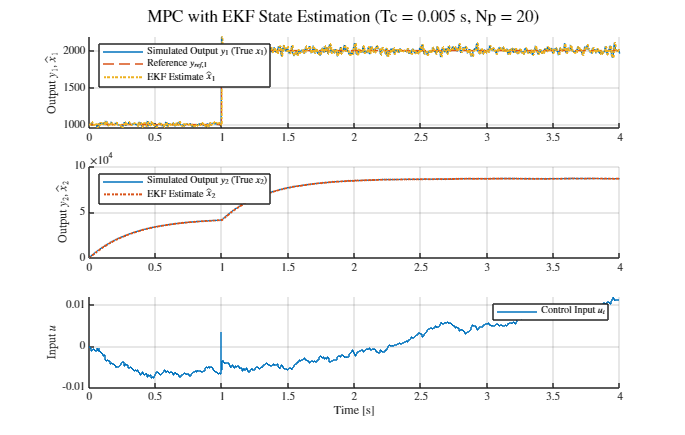


% --- Plotting ---
figure('Position', plotPos2);
% Plot each output separately
subplot(n_outputs + 1, 1, 1);
hold on;
plot((0:N_sim)*Ts_sim, y_sim(1, :), 'DisplayName', 'Simulated Output $y_1$ (True $x_1$)');
plot((0:N_sim)*Ts_sim, y_ref_sim(:), '--', 'DisplayName', 'Reference $y_{ref,1}$');
plot((0:N_sim/M)*Tc, xhat_sim(1, :), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF Estimate $\hat{x}_1$');
ylabel('Output $y_1, \hat{x}_1$');
legend('Location', 'northwest');
grid on;
hold off;

subplot(n_outputs + 1, 1, 2);
hold on;
plot((0:N_sim)*Ts_sim, y_sim(2, :), 'DisplayName', 'Simulated Output $y_2$ (True $x_2$)');
plot((0:N_sim/M)*Tc, xhat_sim(2, :), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF Estimate $\hat{x}_2$');
ylabel('Output $y_2, \hat{x}_2$');
legend('Location', 'northwest');
grid on;
hold off;


% Plot input
subplot(n_outputs + 1, 1, n_outputs + 1);
hold on;
stairs((0:N_sim-1)*Ts_sim, u_sim, 'DisplayName', 'Control Input $u_t$');
ylabel('Input $u$');
xlabel('Time [s]');
legend('Location', 'northeast');
grid on;
hold off;

sgtitle(sprintf('MPC with EKF State Estimation (Tc = %.3f s, Np = %d)', Tc, Np));

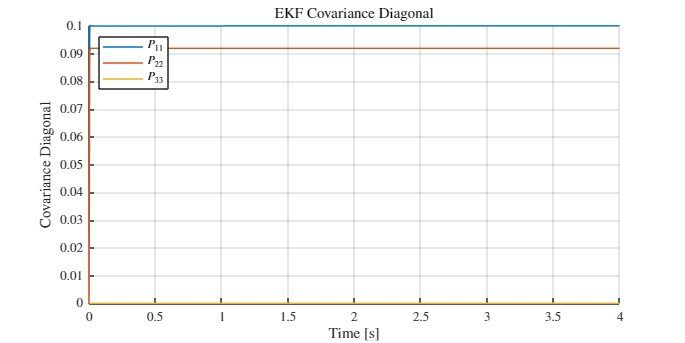


% Plot EKF Covariance Diagonal
figure('Position', plotPos);
hold on;
plot((0:N_sim/M)*Tc, squeeze(P_sim(1,1,:)), 'DisplayName', '$P_{11}$');
plot((0:N_sim/M)*Tc, squeeze(P_sim(2,2,:)), 'DisplayName', '$P_{22}$');
plot((0:N_sim/M)*Tc, squeeze(P_sim(3,3,:)), 'DisplayName', '$P_{33}$');
ylabel('Covariance Diagonal');
xlabel('Time [s]');
legend('Location', 'northwest');
title('EKF Covariance Diagonal');
grid on;
hold off;

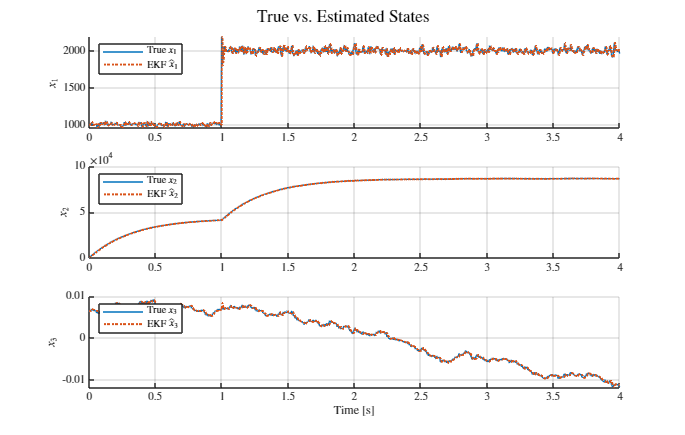



% Optional: Plot true states and estimated states
figure('Position', plotPos2);
subplot(3,1,1);
hold on;
plot((0:N_sim)*Ts_sim, x_sim(1,:), 'DisplayName', 'True $x_1$');
plot((0:N_sim/M)*Tc, xhat_sim(1,:), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF $\hat{x}_1$');
ylabel('$x_1$'); grid on; legend('Location', 'northwest');
hold off;

subplot(3,1,2);
hold on;
plot((0:N_sim)*Ts_sim, x_sim(2,:), 'DisplayName', 'True $x_2$');
plot((0:N_sim/M)*Tc, xhat_sim(2,:), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF $\hat{x}_2$');
ylabel('$x_2$'); grid on; legend('Location', 'northwest');
hold off;

subplot(3,1,3);
hold on;
plot((0:N_sim)*Ts_sim, x_sim(3,:), 'DisplayName', 'True $x_3$');
plot((0:N_sim/M)*Tc, xhat_sim(3,:), ':', 'LineWidth', 1.5, 'DisplayName', 'EKF $\hat{x}_3$');
ylabel('$x_3$'); xlabel('Time [s]'); grid on; legend('Location', 'northwest');
hold off;
sgtitle('True vs. Estimated States');